# Como utilizar comando para crear mapas de acupacion

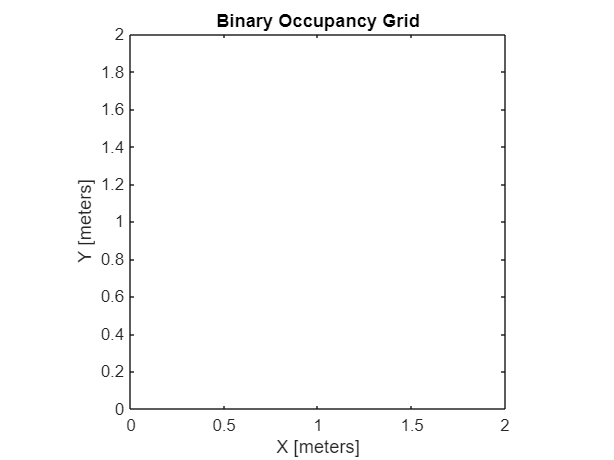

clc
close all
clf

% Creacion de mapas binarios.

% Cuadrícula de ocupación binaria
% El binaryOccupancyMap crea un objeto de mapa de ocupación 2-D, que puede
% usar para representar y visualizar un espacio de trabajo de robot,
% incluidos los obstáculos.
ancho = 2; %  Ancho de celda en metros
alto  = 2 ; %  Alto de celda en metros
resolucion = 5; % Numero de celdas por metro.
% Tamaño de celda es de 1m/resolucion = 1m/5=.2m

% Crea una espacio de trabajo de 2 m x 2 m, con 5 celdas por metro.
map = binaryOccupancyMap(ancho, alto,resolucion);
show(map);

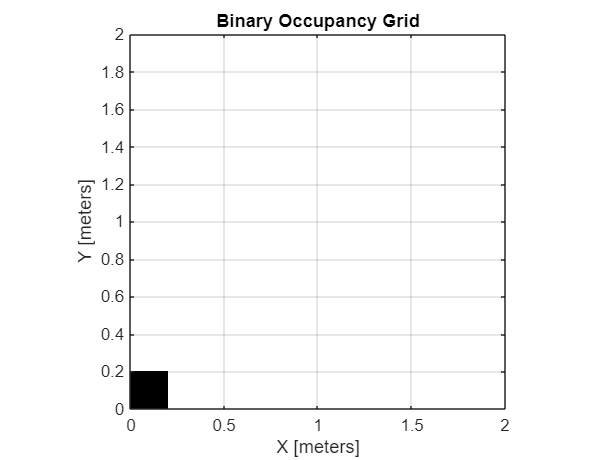

% crea una cuadrícula de ocupación binaria 2-D con un width y
% una height de 10 m.
% La resolución de cuadrícula predeterminada es una celda por metro.

% Se  visualiza una celda

setOccupancy(map,[10 1],1,'grid')
show(map)
grid

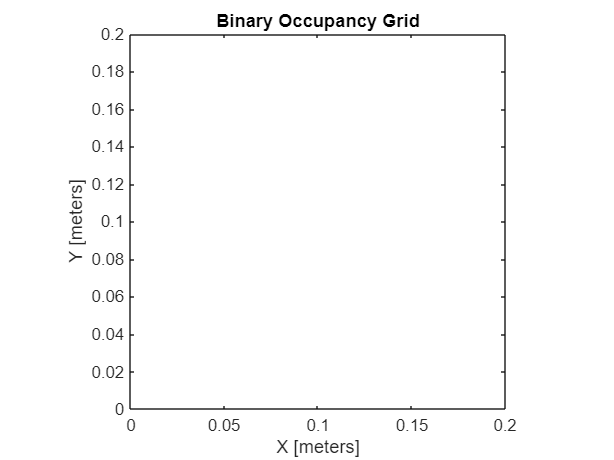

figure(2)
celda = binaryOccupancyMap(1,1,5,'grid');
show(celda);

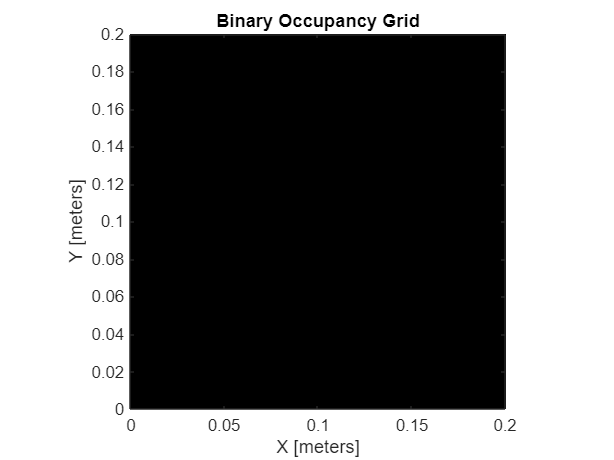

setOccupancy(celda,[0 0],1)
show(celda)

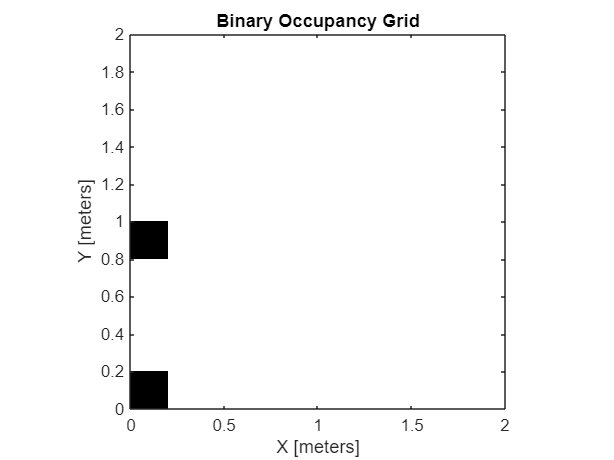

setOccupancy(map,[0 1],1)
show(map)

Argumentos de entrada Ancho entero positvio Alto entero positivo Resolucion numero de filas y columna de la regilla.

## Creacion de celdas ocupadas

setOccupancy(map,xy,occval) asigna valores de ocupación, occval, a la matriz de entrada de coordenadas globales, xy en la cuadrícula de ocupación, map. Cada fila de la matriz, xy, es un punto en el mundo y se representa como un par de coordenadas [x y]. occval es una matriz escalar o de una sola columna de la misma longitud que xy . mapa, posicion de la celda, ocupacion

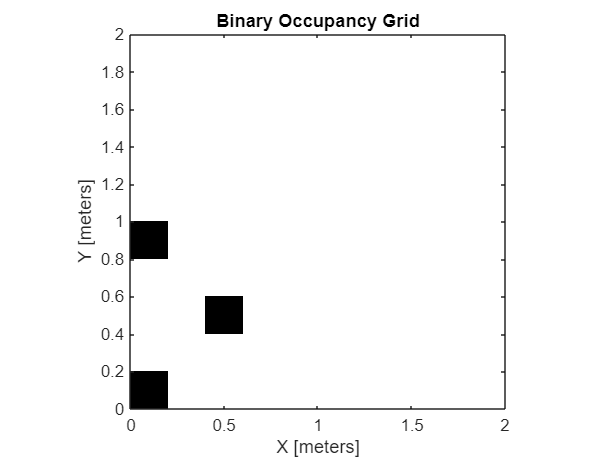

setOccupancy(map,     [.5 .5],       1);
show(map);

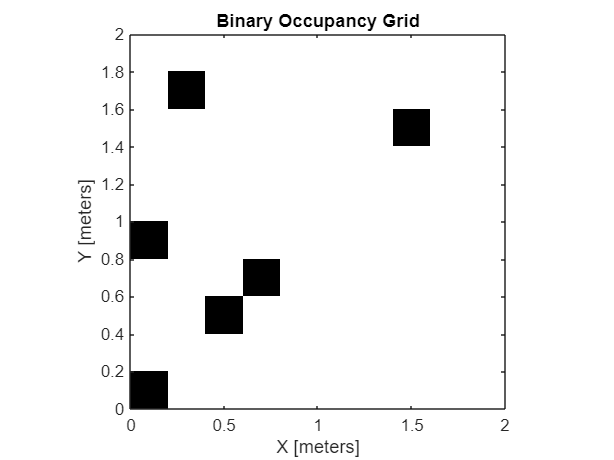


setOccupancy(map,     [1.6 1.6; .8 .8; .4 1.8],      [1 1 1]);
show(map);

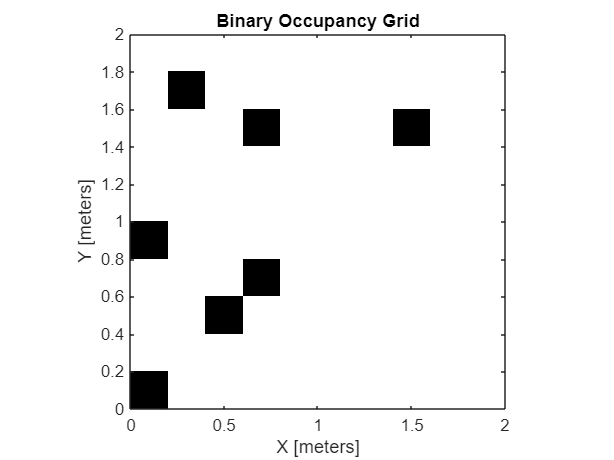


setOccupancy(map,     [3, 4], 1, 'grid');
show(map);

## Creacion de celdas ocupadas

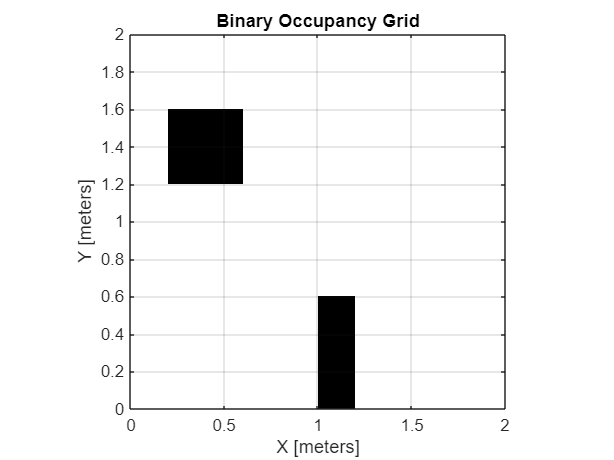

clf
map2 = binaryOccupancyMap(ancho, alto,resolucion);
x = [1.2; 1.2; 1.2; 0.4; 0.4; 0.6 ; 0.6];
y = [0.2; 0.4; 0.6; 1.4; 1.6; 1.4 ; 1.6];

setOccupancy(map2, [x y], ones(7,1))
figure
show(map2)
grid

## Informacion de la grilla

Convierta coordenadas mundiales en índices de cuadrícula

ij = world2grid(map2, [x y]);

## Activar obstaculos utilizando la grilla.

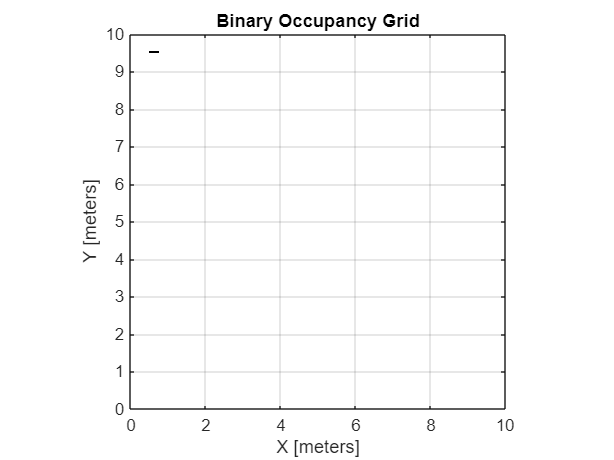

clear
map3 = binaryOccupancyMap(10,10,20); % 10 metros, 10 metros, 20 celdas /1m
i = 10*[1; 1; 1; 1; 1];
j = 10+[1; 2; 3; 4; 5];
ocv=[1 1 1 1 1];
setOccupancy(map3,   [i j], ocv, "grid");
show(map3)
grid

% Realice variaciones a los arreglos i, j y ocv para obtener diferentes
% conjuntos de celdas ocupadas en el mapa.

## Insert Laser Scans into Binary Occupancy Map

Datos de entrada de la pose de vehiculo, rangos y angulos y el maximo rango del sensor laser scan.

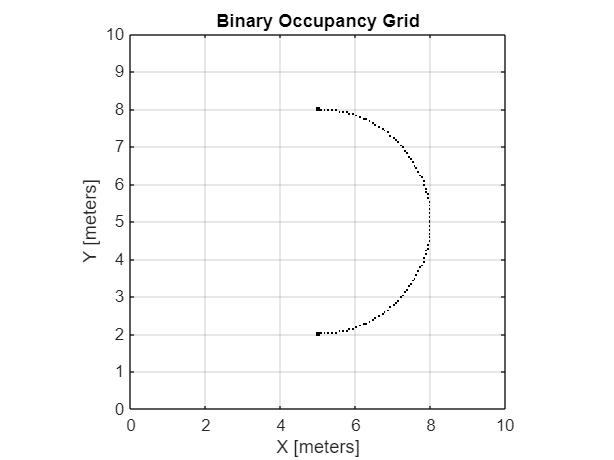

map3 = binaryOccupancyMap(10,10,20);
pose = [5,5,0];   % X, Y , Angulo
ranges = 3*ones(100,1);
angles = linspace(-pi/2,pi/2,100);
maxrange = 20;
% Cree un objeto LIDARScan con los rangos y ángulos especificados.
scan = lidarScan(ranges,angles);

% Inserte los datos del escaneo láser en el mapa de ocupación.
insertRay(map3,pose,scan,maxrange);

% Muestre el mapa para ver los resultados de insertar el escaneo láser.
show(map3)
grid


% Verifique la ocupación del lugar directamente en frente del vehículo.
getOccupancy(map3,[8 5])

ans = logical
   1


## Obtener valores de ocupación y verifique el estado de ocupación

Acceda a los valores de ocupación y verifique su estado de ocupación en función de los umbrales ocupados y libres del objeto occupancyMap.

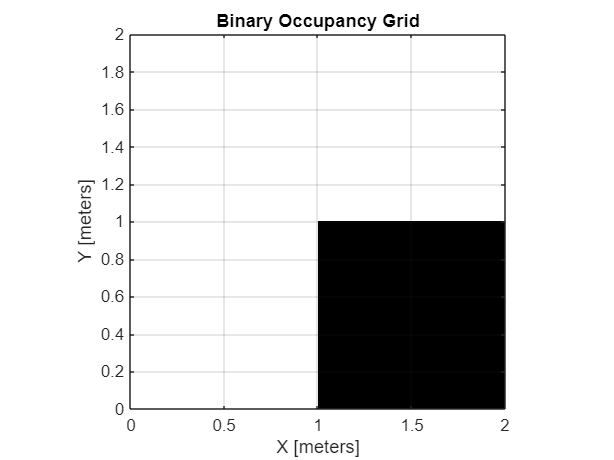

% Cree una matriz y rellénela con valores. Utilice esta matriz para crear
% un mapa de ocupación.

p = zeros(20,20);
p(11:20,11:20) = ones(10,10);
map = binaryOccupancyMap(p,10);
show(map)
grid

% Obtenga la ocupación de diferentes ubicaciones y verifique sus estados
% de ocupación. El estado de ocupación devuelve 0 para espacio libre y 1
% para espacio ocupado. Los valores desconocidos devuelven -1.
pocc = getOccupancy(map,[1.5 1;2 3], "local")

pocc = 2×1 logical array
   1
   0


occupied = checkOccupancy(map,[1.5 1])  % Verifica la ocupacion

occupied = 1

pocc2 = getOccupancy(map,[5 5;8 9],'grid')  % Retorna valores de ocupación de la celda especificada.

pocc2 = 2×1 logical array
   0
   0
